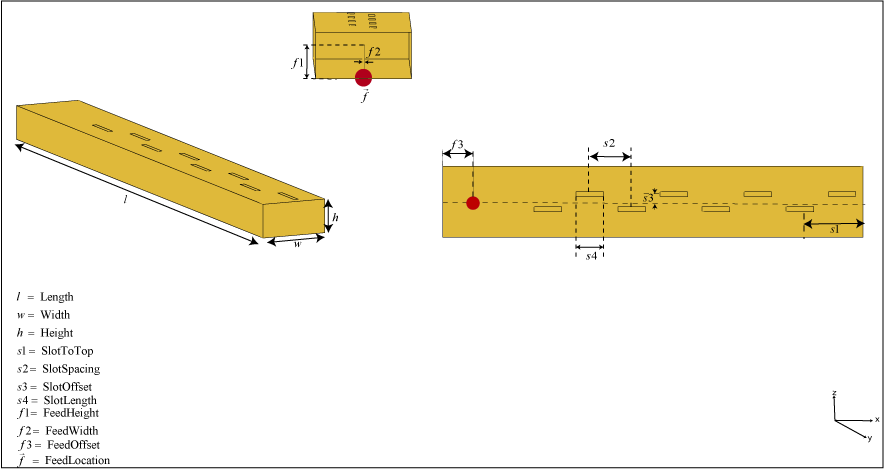

[https://www.mathworks.com/help/antenna/ref/waveguideslotted.html](https://www.mathworks.com/help/antenna/ref/waveguideslotted.html)

Number_of_slots = 11; 

Slots_pos_center_rel =[0,1.06e-3,1.06e-3,2.88e-3,2.88e-3,4.64e-3,2.88e-3,2.88e-3,1.06e-3,1.06e-3,0]

Slots_pos_center_rel =          0    0.0011    0.0011    0.0029    0.0029    0.0046    0.0029    0.0029    0.0011    0.0011         0


slots_shape = antenna.Rectangle('Length',14.63e-3,'Width',2.09e-3);
m = metal('Copper'); 

l= 290;
w =22.9;
h =10.22;



s1=42.07e-3;
s2=19.29e-3;

%last to waveguide end 42.07mm
%slots spacing 19.29mm
% spacing_elements = 200

m1_slots =[30e-3,30e-3,30e-3,30e-3,5e-3,30e-3,5e-3,30e-3,5e-3,30e-3];

m1 =  waveguideSlotted('Length',l*1e-3,'Width',w*1e-3,'Height',h*1e-3, 'NumSlots',Number_of_slots,...
      'Slot',slots_shape,...
        'SlotOffset',Slots_pos_center_rel, ...
      'Tilt',180  ,'TiltAxis',[0 0 1],'Conductor',m,'SlotSpacing',s2,'FeedOffset',[-1.4e-3,0],'FeedHeight',1e-3,'Feedwidth',1e-4);
% 
% m2 =   waveguideSlotted('Length',l*1e-3,'Width',w*1e-3, 'NumSlots',Number_of_slots,...
%       'Slot',slots_shape,...
%       'SlotOffset',Slots_pos_center_rel, ...
%       'Conductor',m,'SlotSpacing',s2);

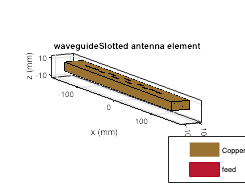

figure;
show(m1)

% mla = linearArray('ElementSpacing',(spacing_elements)*1e-3)
% mla.Element = [m1,m2];
% figure;
% show(mla);

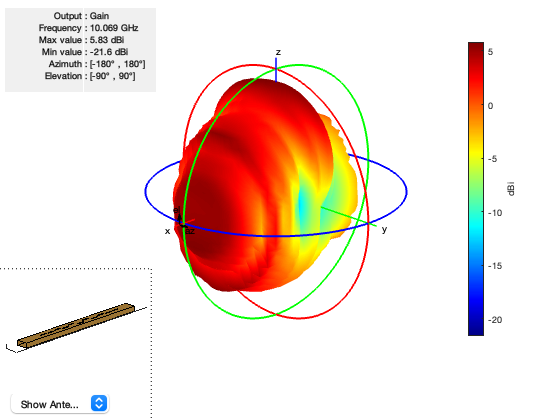

figure;
pattern(m1,10.069e9);

% figure;
% EHfields(mla,3e9)

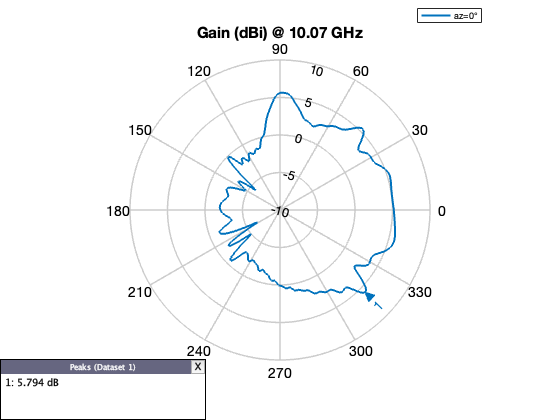

figure;
patternElevation(m1,10.069e9)

% saveas(gcf,'radiation_curve','png')

% freq = 9.5e9:0.1e9:11e9
% for freq = freq
% figure;
% patternElevation(m1,freq)
% end

% freqs=8.5e9:0.005e9:12e9;
% s=sparameters(m1,freqs);
% s.Parameters;
% figure;
% rfplot(s)

% figure;
% current(mla,5e9)

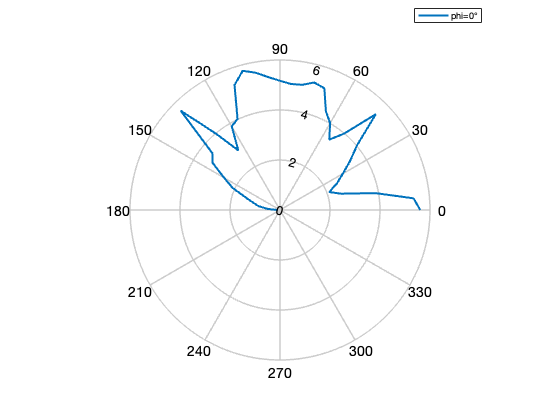

[D,az,el] = pattern(m1,10.069e9);
phi = az';
theta = 90-el;
MagE = D';
% MagE=transpose(MagE)
figure;
patternCustom(MagE, theta, phi,'CoordinateSystem','polar',...
    'Slice','phi','SliceValue',0);